open_system('task_3');
set_param('task_3/y', 'VariableName', 'y')
set_param('task_3/y1', 'VariableName', 'y1')
set_param('task_3/y2', 'VariableName', 'y2')
set_param('task_3/g', 'VariableName', 'g')

out = sim('task_3');

plot(out.y,'c', 'LineWidth', 1.5)
hold on
plot(out.y1, 'm--', 'LineWidth', 2)
plot(out.y2, 'b:','LineWidth', 2)
t = linspace(0.01, 500, 1000)

t =     0.0100    0.5105    1.0110    1.5115    2.0120    2.5125    3.0129    3.5134    4.0139    4.5144    5.0149    5.5154    6.0159    6.5164    7.0169    7.5174    8.0178    8.5183    9.0188    9.5193   10.0198   10.5203   11.0208   11.5213   12.0218   12.5223   13.0228   13.5232   14.0237   14.5242   15.0247   15.5252   16.0257   16.5262   17.0267   17.5272   18.0277   18.5281   19.0286   19.5291   20.0296   20.5301   21.0306   21.5311   22.0316   22.5321   23.0326   23.5331   24.0335   24.5340


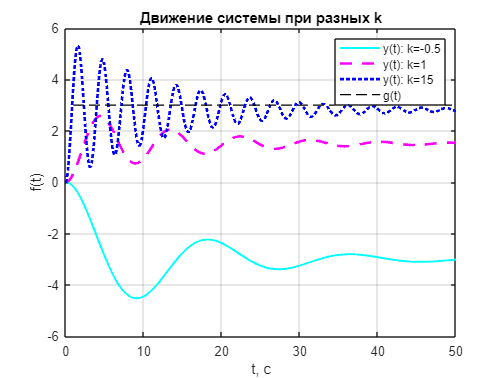


%plot(out.g,'k--', 'LineWidth', 1)
plot(3 * sign(t),'k--', 'LineWidth', 1)
%plot(out.g, 'LineWidth', 2,  Color='#26d74c')
%plot(out.e, 'LineWidth', 2,  Color='#26d74c')
%plot(out.e1, 'LineWidth', 2,  Color='#e67291')
%plot(out.e2, 'LineWidth', 2,  Color='#e67291')


grid()
%title('Ошибки движения системы при разных k')
title('Движение системы при разных k')
%title('Движение системы при k = 15')
legend('y(t): k=-0.5', 'y(t): k=1', 'y(t): k=15', 'g(t)')
%legend('y(t)','g(t)')
ylabel('f(t)')
xlabel('t, с')
xlim([0 50])
%ylim([0 3.1])
hold off